
im=imread('saturn.png');

im = rgb2gray(im);
fprintf("original image");

original image

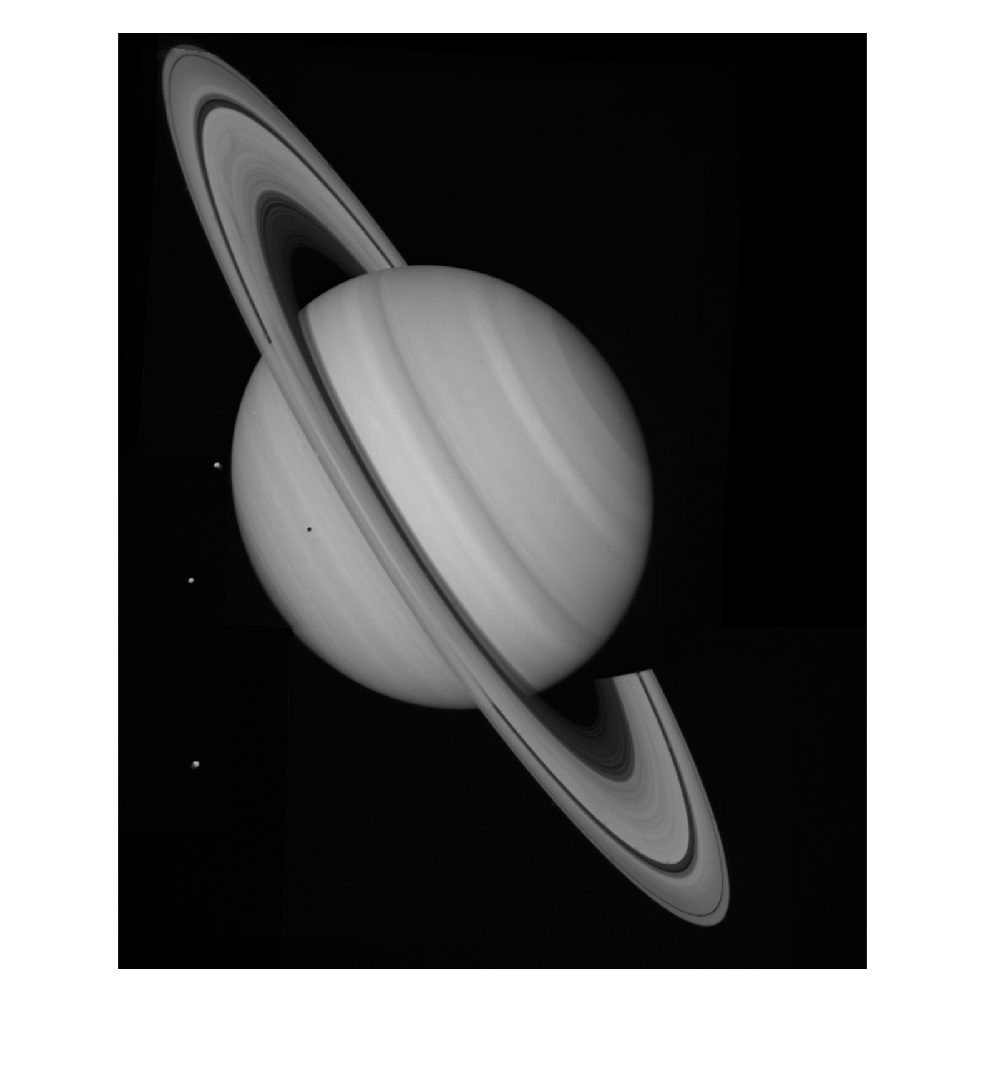

imshow(im);


x=fft2(im);
%{
x = abs(x);
x = fftshift(x);
x = log(1+abs(x));
imagesc(x);
%}
nn=1*1e+8;
%nn=1*1e+10;
%disp(x);

fprintf("x(10,10), x(10,11) x(11,10), x(11,11) numbers before");

x(10,10), x(10,11) x(11,10), x(11,11) numbers before

disp(x(10,10));

  -2.1550e+05 - 8.2469e+05i



disp(x(10,11));

  -7.1755e+04 - 9.5487e+04i



disp(x(11,10));

  -9.6369e+04 - 5.9753e+04i



disp(x(11,11));

   4.8371e+04 + 3.5412e+05i




x(10,10)=x(10,10)+nn; x(10,11)=x(10,11)+nn;
x(11,10)=x(11,10)+nn; x(11,11)=x(11,11)+nn;
fprintf("x indexing");

x indexing

%disp(x([10:11,10:11]));
disp(x([10 11],[10 11]));

   1.0e+08 *

   0.9978 - 0.0082i   0.9993 - 0.0010i
   0.9990 - 0.0006i   1.0005 + 0.0035i





fprintf("x(10,10), x(10,11) x(11,10), x(11,11) numbers after");

x(10,10), x(10,11) x(11,10), x(11,11) numbers after

disp(x(10,10));

   9.9785e+07 - 8.2469e+05i



disp(x(10,11));

   9.9928e+07 - 9.5487e+04i



disp(x(11,10));

   9.9904e+07 - 5.9753e+04i



disp(x(11,11));

   1.0005e+08 + 3.5412e+05i



%increased to not just include (10 ,11) (10,11) row,columsn but include 9 and 12 to 
%get whole 4 by 4 matrix since medfilt2 uses 3x3 matrix by defauly
%z = x([9 10 11 12],[9 10 11 12]);

z = x(9:12,9:12);

%{
fprintf("z numbers")
disp(z(1,1));
disp(z(1,2));
disp(z(2,1));
disp(z(2,2));
%}
fprintf("z numbers")

z numbers

disp(z(2,2));

   9.9785e+07 - 8.2469e+05i



disp(z(2,3));

   9.9928e+07 - 9.5487e+04i



disp(z(3,2));

   9.9904e+07 - 5.9753e+04i



disp(z(3,3));

   1.0005e+08 + 3.5412e+05i




%checking if x and y are the same for 10,10 10,11 etc.
fprintf("disp(z) before medfilt");

disp(z) before medfilt

disp(z);

   1.0e+08 *

   0.0031 + 0.0037i   0.0013 + 0.0012i   0.0001 - 0.0071i   0.0007 - 0.0012i
   0.0021 + 0.0019i   0.9978 - 0.0082i   0.9993 - 0.0010i  -0.0015 + 0.0033i
  -0.0041 - 0.0056i   0.9990 - 0.0006i   1.0005 + 0.0035i   0.0012 - 0.0006i
  -0.0010 - 0.0020i   0.0007 + 0.0022i   0.0009 - 0.0021i  -0.0018 + 0.0002i



z =medfilt2(real(z));
%x = medfilt2(real(x));
fprintf("disp(z) after medfilt");

disp(z) after medfilt

disp(z);

   1.0e+05 *

         0    1.2868    0.1194         0
    1.2868    3.0536    1.2868    0.1194
         0    2.1173    1.1780         0
         0         0    0.7347         0



%x = medfilt2((z));

%{
x(10,10) = z(1,1);
x(10,11) = z(1,2);
x(11,10) = z(2,1);
x(11,11) = z(2,2);
%}
%need to probably replace whole 4x4 matrix with new z patch

%{
x(9,9) = z(1,1);
x(9,10) = z(1,2);
x(9,11) = z(1,3);
x(9,12) = z(1,4);
x(10,9) = z(2,1);

x(10,10) = z(2,2);
x(10,11) = z(2,3);

x(10,12) = z(2,4);

x(11,9) = z(3,1);

x(11,10) = z(3,2);
x(11,11) = z(3,3);

x(11,12) = z(3,4);

x(12,9) = z(4,1);
x(12,10) = z(4,2);
x(12,11) = z(4,3);
x(12,12) = z(4,4);
%}

x(9:12,9:12) = z;

fprintf("x(10,10), x(10,11) x(11,10), x(11,11) numbers after replace");

x(10,10), x(10,11) x(11,10), x(11,11) numbers after replace

disp(x(10,10));

   3.0536e+05



disp(x(10,11));

   1.2868e+05



disp(x(11,10));

   2.1173e+05



disp(x(11,11));

   1.1780e+05




y=real(ifft2(x));
%y = ifft2(x);
%y = real(y);
%z_real= real(ifft2(z));

fprintf("y");

y

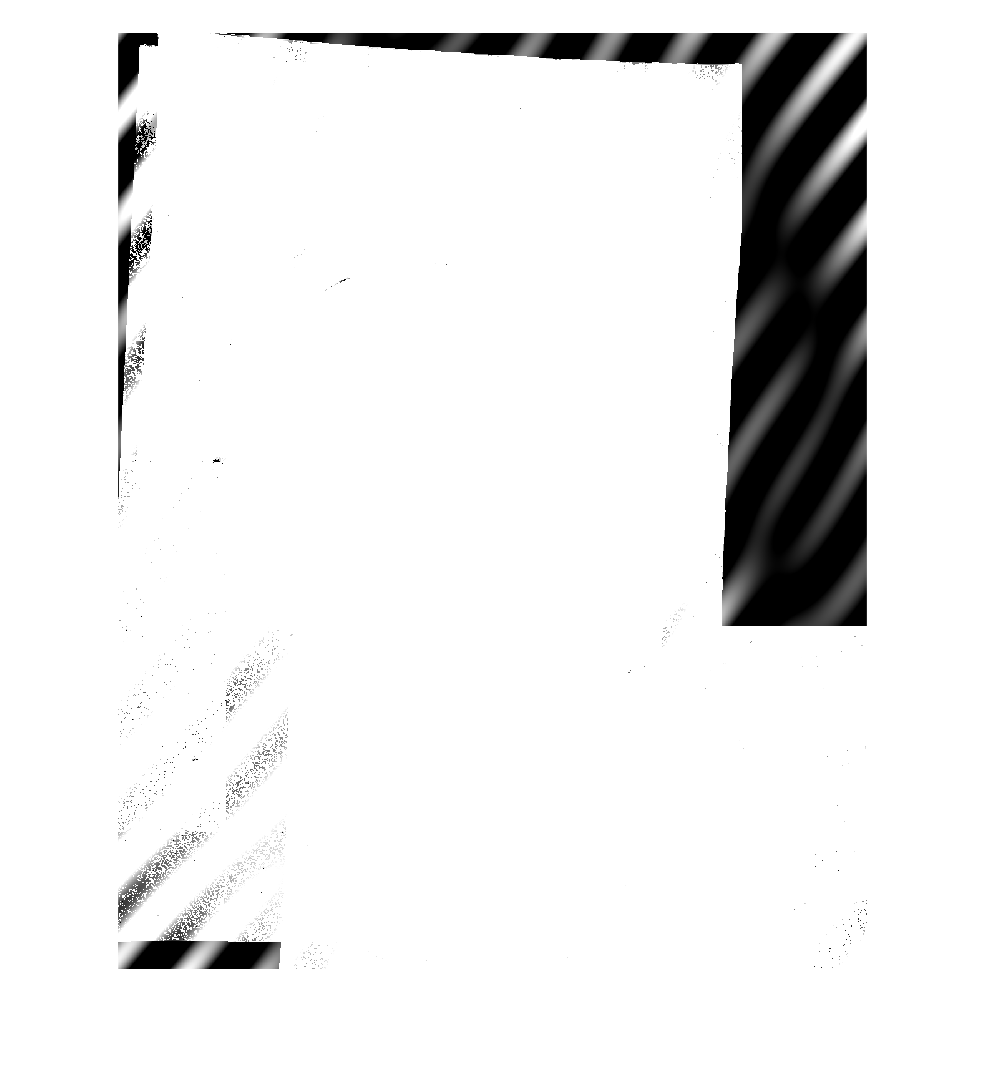

imshow(y);


%{
fprintf("z_real (should be fixed noise)");
imshow(z_real)
%}

%{
im=imread('saturn.png');
im = rgb2gray(im);
imshow(im);
x=fft2(im);
nn=1*1e+8;%8
x(10,10)=x(10,10)+nn; x(10,11)=x(10,11)+nn;
x(11,10)=x(11,10)+nn; x(11,11)=x(11,11)+nn;
y=real(ifft2(x));
imshow(y);
%}